clc
clear

disp("Initilization Procedure")

Initilization Procedure


model.Parameters

param = control.calculateOperatingPoint(param);

Calculate Operating Point for T_a = 293.150000 [K]


param = model.calculateModel(param);

Calculate bilinear model matrices
Calculate linearisation decoupled
Calculate linearisation coupled
Testing controlability
Testing T_ref


simtime = 10*60;
A_JOHNogKarsten = cell(1,param.n)

A_JOHNogKarsten = 1×4 cell array
    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}


for i = 1:param.n
    A_JOHNogKarsten{i} = [-(param.ctrl.q_OP(i)/param.thermo.V_w(i) + param.thermo.B(i)/(param.thermo.C_w*param.thermo.rho_w*param.thermo.V_w(i))) param.thermo.B(i)/(param.thermo.C_w*param.thermo.rho_w*param.thermo.V_w(i)), 0;
                                param.thermo.B(i)/(param.thermo.C_a*param.thermo.rho_a*param.thermo.V_a(i)), -(param.ctrl.Q(i)/param.thermo.V_a(i) +param.thermo.B(i)/(param.thermo.C_a*param.thermo.rho_a*param.thermo.V_a(i))),0;
                                0, 1, 0];
end
param.model.A = blkdiag(A_JOHNogKarsten{:})

param = struct with fields:
    thermo: [1×1 struct]
      ctrl: [1×1 struct]
      pipe: [1×1 struct]
      pump: [1×1 struct]
     model: [1×1 struct]
         n: 4


eig(blkdiag(A_JOHNogKarsten{:}))

ans =          0
         0
         0
         0
   -4.0442
   -0.0312
   -0.0311
   -4.0059
   -0.0311
   -4.0059


%eig(param.model.A)



%param.model.A = -10*eye(12);
%param.model.B_Bar = blkdiag(ones(3,1),ones(3,1),ones(3,1),ones(3,1));
%param.model.B = blkdiag(ones(3,1),ones(3,1),ones(3,1),ones(3,1));
%param.model.B = ones(12,4);
%param.model.B_Bar = ones(12,4);

## Control

[param.ctrl.Ks res] = control.DesignProcedure1(param,0); 

sol = struct with fields:
    solvertime: 0
          info: 'Solver not found (mosek)'
       problem: -3
    yalmiptime: 0.6210


You have NaNs in model (<a href="yalmip.github.io/naninmodel">learn to debug</a>)


Error using  * 
Multiplying NaN with an SDPVAR makes no sense.

Error in control.DesignProcedure1 (line 44)
    LPV = [cali_R * param.model.A + param.model.A.' * cali_R + tau*(K.'*K), cali_R*param.model.B; param.model.B.'*cali_R, -tau*eye(4)];

% param.ctrl.Ks = control.DesignProcedure2(param,0);

%param.ctrl.Ks = control.DesignProcedureDScalingDiag(param,0);
%param.ctrl.Ks = control.DesignProcedureFunky(param,0);
%param.ctrl.Ks = control.DesignRobust(param,0

## Scaled design

yalmip('clear')   
Q = cell(1,param.n);
y = cell(1,param.n);
for i=1:param.n
    Q{i} = sdpvar(3);
    y{i} = sdpvar(3,3,'full');    
end
cali_Q = blkdiag(Q{:});
Y = blkdiag(y{:});
%Lyapuanov
constraints = [param.model.A*cali_Q+cali_Q*param.model.A.'+ Y*eye(12) + eye(12).'*Y.' <=0];
constraints = [constraints,  cali_Q >= 0];

options = sdpsettings('verbose',0,'solver','mosek');
sol = optimize(constraints,[],options);
L = value(Y)/value(cali_Q);
K = blkdiag(param.ctrl.Ks(:,:,1),param.ctrl.Ks(:,:,2),param.ctrl.Ks(:,:,3),param.ctrl.Ks(:,:,4));

Ak = param.model.A + param.model.B_Bar * K + L * eye(12);
Bk = -L;
% Ak = param.model.A + param.model.B_Bar * K;
% Ak = zeros(12);
% Bk = eye(12);
% b1 = blkdiag([0;1;0],[0;1;0],[0;1;0],[0;1;0]);
b1 = -blkdiag([0;0;1],[0;0;1],[0;0;1],[0;0;1]);
c1 = blkdiag([0 1 0],[0 1 0],[0 1 0],[0 1 0]);

A = [param.model.A zeros(12) ; zeros(12) Ak];
B1 = [b1 ; zeros(12,4)];
B2 = [param.model.B_Bar zeros(12); zeros(12,4) Bk];
C1 = [c1 zeros(4,12)];
C2 = [zeros(4,12) K ; eye(12) zeros(12)];
D11 = zeros(4);
D12 = zeros(4,16);
D21 = zeros(16,4);
D22 = zeros(16);

ssP = [A B1 B2 ; C1 D11 D12 ; C2 D21 D22] %(3.6)

ssP =    -0.0500    0.0250         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0   -0.1296         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    2.9902   -3.9869         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0    1.0000         0         0         0         0         0         0         0         0         0  

ssN11 = (A + B2/(eye(16) - D22)*C2);
ssN12 = (B1 + B2/(eye(16) - D22)*D21);
ssN21 = (C1 + D12/(eye(16) - D22)*C2);
ssN22 = (D11 + D12/(eye(16) - D22) * D21);
ssN = [ssN11, ssN12 ; ssN21, ssN22] %(3.7)

ssN =    -0.0500    0.0250         0         0         0         0         0         0         0         0         0         0    1.2795   -7.8844   -1.6823         0         0         0         0         0         0         0         0         0         0         0         0         0
    2.9902   -3.9869         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0    1.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0   -1.0000         0         0         0
         0         0         0   -0.0501    0.0251         0         0         0         0         0         0         0         0         0         0 


s = tf('s');
N = ssN21 / (s*eye(24) - ssN11) * ssN12 + ssN22

N =
 
  From input 1 to output...
                            2.481 s^2 + 2.498 s + 0.6294
   1:  ----------------------------------------------------------------------
       s^6 + 4.257 s^5 + 23.49 s^4 + 35.12 s^3 + 21.84 s^2 + 6.101 s + 0.6294
 
   2:  0
 
   3:  0
 
   4:  0
 
  From input 2 to output...
   1:  0
 
                            2.595 s^2 + 2.579 s + 0.6413
   2:  ----------------------------------------------------------------------
       s^6 + 4.264 s^5 + 23.86 s^4 + 35.78 s^3 + 22.27 s^2 + 6.219 s + 0.6413
 
   3:  0
 
   4:  0
 
  From input 3 to output...
   1:  0
 
   2:  0
 
                            2.552 s^2 + 2.534 s + 0.63
   3:  --------------------------------------------------------------------
       s^6 + 4.257 s^5 + 23.49 s^4 + 35.12 s^3 + 21.85 s^2 + 6.105 s + 0.63
 
   4:  0
 
  From input 4 to output...
   1:  0
 
   2:  0
 
   3:  0
 
                            2.532 s^2 + 2.534 s + 0.6312
   4:  -----------------------------------------------

## Test small case

BlueM = inv(eye(16) - [zeros(12,16);K zeros(4)]) * [eye(12) zeros(12,4) ; zeros(4,16)];
ssG = [param.model.A, b1; c1, zeros(4)] + [zeros(12), param.model.B_Bar; zeros(4,16)]*BlueM;

G = ssG(13:end,1:12)/(s*eye(12) - ssG(1:12,1:12))*ssG(1:12,13:end) + ssG(13:end,13:end)

G =
 
  From input 1 to output...
                    5.031
   1:  --------------------------------
       s^3 + 2.757 s^2 + 18.6 s + 5.031
 
   2:  0
 
   3:  0
 
   4:  0
 
  From input 2 to output...
   1:  0
 
                     5.127
   2:  ---------------------------------
       s^3 + 2.764 s^2 + 18.97 s + 5.127
 
   3:  0
 
   4:  0
 
  From input 3 to output...
   1:  0
 
   2:  0
 
                    5.031
   3:  --------------------------------
       s^3 + 2.757 s^2 + 18.6 s + 5.031
 
   4:  0
 
  From input 4 to output...
   1:  0
 
   2:  0
 
   3:  0
 
                    5.031
   4:  --------------------------------
       s^3 + 2.757 s^2 + 18.6 s + 5.031
 
Continuous-time transfer function.


## Test bigger case

An = [param.model.A+param.model.B_Bar*K*eye(12)];
Bn = [b1, param.model.B_Bar];
Cn = [c1; K*eye(12)];
Dn = [zeros(8,8)];

Nn = Cn/(s*eye(12) - An)*Bn+Dn;

Mn = Nn(5:end,5:end);
hinfnorm(Mn)

ans = 1.9557



Mn2 = K*eye(12)/(s*eye(12) - An)*param.model.B_Bar + zeros(4);
[val, freq] = hinfnorm(Mn2)

val = 1.9557

freq = 3.9296


An2 = An;
Bn2 = param.model.B_Bar;
Cn2 = K*eye(12); 
Dn2 = zeros(4);
Mn2.InputName = "w";
Mn2.OutputName = "z";
T = connect(Mn2,"w","z");

% bounds = mu(T,[-4,0])
[bounds,muinfo] = mussv(T,[-1,0;-1,0;-1,0;-1,0]);

Computing bounds... Points completed: 42/42
Computing peak...  Percent completed: 100/100


[VDelta,VSigma,VLmi] = mussvextract(muinfo);
muinfo.bnds.ResponseData

ans = ans(:,:,1) =

    1.0021    1.0000


ans(:,:,2) =

    0.9751         0


ans(:,:,3) =

   1.0e-03 *

    0.2000         0


ans(:,:,4) =

   1.0e-03 *

    0.2000         0


ans(:,:,5) =

   1.0e-03 *

    0.2000         0


ans(:,:,6) =

   1.0e-03 *

    0.2001         0


ans(:,:,7) =

   1.0e-03 *

    0.2001         0


ans(:,:,8) =

   1.0e-03 *

    0.2001         0


ans(:,:,9) =

   1.0e-03 *

    0.2002         0


ans(:,:,10) =

   1.0e-03 *

    0.2004         0


ans(:,:,11) =

   1.0e-03 *

    0.2006         0


ans(:,:,12) =

   1.0e-03 *

    0.2009         0


ans(:,:,13) =

   1.0e-03 *

    0.2014         0


ans(:,:,14) =

   1.0e-03 *

    0.2021         0


ans(:,:,15) =

   1.0e-03 *

    0.2031         0


ans(:,:,16) =

   1.0e-03 *

    0.2043         0


ans(:,:,17) =

   1.0e-03 *

    0.2058         0


ans(:,:,18) =

   1.0e-03 *

    0.2074         0


ans(:,:,19) =

   1.0e-03 *

    0.2092         0


ans(:,:,20) =

   1.0e-03 *

    0.2113    



Delta = VDelta.ResponseData(:,:,end);
DL = VSigma.DLeft.ResponseData(:,:,end);
DR = VSigma.DRight.ResponseData(:,:,end);
[norm(DL*Delta/DR) bounds(1).ResponseData(end)]

ans = 1.0e-10 *

         0    0.2624


yalmip('clear')
gamma = sdpvar(1);
% D = diag(sdpvar(4,1));
D = diag([2,3,4,5])

D =      2     0     0     0
     0     3     0     0
     0     0     4     0
     0     0     0     5


P = cell(1,param.n);
for i=1:param.n
    P{i} = sdpvar(3);
end
cali_P = blkdiag(P{:});
% Bounded real lemma
% constraints = [[An2'*cali_P+cali_P*An2, cali_P*Bn2, Cn2';
%                 Bn2'*cali_P, -gamma*eye(4), Dn2';
%                 Cn2, Dn2, -gamma*eye(4)] <=0];
% Scaled bounded real lemma
constraints = [[An2'*cali_P+cali_P*An2, cali_P*Bn2*D, Cn2'*D;
                D'*Bn2'*cali_P, -gamma*D, Dn2'*D;
                D'*Cn2, D'*Dn2, -gamma*D] <=0];

constraints = [constraints,  cali_P >= 0, D >= 0];

options = sdpsettings('verbose',0,'solver','mosek');
sol = optimize(constraints,gamma,options);
value(gamma)

ans = 9.7064

eig(value(cali_P))

ans =    39.1564
   51.4630
   85.2165
   99.1228
  204.4682
  245.1419
  266.6629
  293.7861
  313.0670
  375.4439


yalmip('clear')

M= [-1 -1; 3 3];
P = diag(sdpvar(2,1));
gamma = sdpvar(1);
constraints = [M'*P*M-gamma^2*P <= 0]

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                           Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Matrix inequality (polynomial) 2x2|              1 to 9|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++


constraints = [constraints, P >= 0, gamma >= 0]

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                           Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Matrix inequality (polynomial) 2x2|              1 to 9|
|   #2|                Matrix inequality 2x2|              1 to 1|
|   #3|          Element-wise inequality 1x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++


options = sdpsettings('verbose',0,'solver','mosek');
sol = optimize(constraints,gamma,options);

value(gamma)

ans = NaN

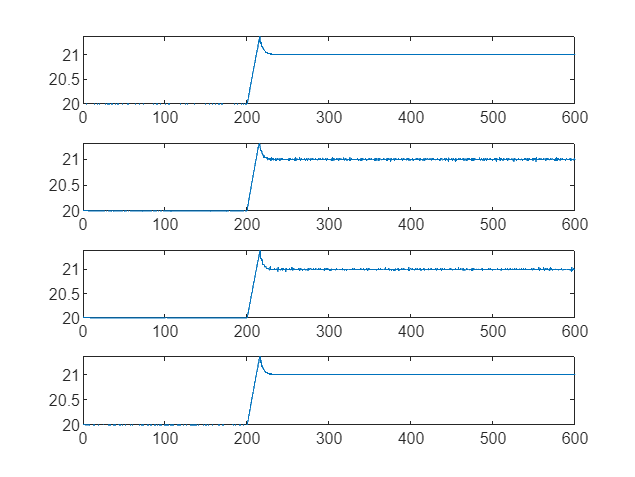

for i=1:4
    x0 = [param.ctrl.T_wOP(i); param.ctrl.T_aOP(i); 0];
    [t,x] = ode45(@(t,x)model.decoupledDynamics(t,x,i,param,200),[0 simtime],x0);
    decoupledResults(i).time = t;
    decoupledResults(i).Tw = x(:,1);
    decoupledResults(i).Ta = x(:,2);
    decoupledResults(i).T = x(:,3);
end
figure()
tiledlayout('vertical')
for i=1:4
    nexttile
    plot(decoupledResults(i).time,decoupledResults(i).Ta-273.15)
end

x0 = [param.ctrl.T_wOP.'; param.ctrl.T_aOP.'; zeros(4,1)];
options = odeset('RelTol',1e-8,'AbsTol',1e-10);
[t,x] = ode45(@(t,x)model.coupledDynamics(t,x,param,200),[0 simtime],x0,options);
coupledResults.time = t;
coupledResults.Tw = x(:,1:4);
coupledResults.Ta = x(:,5:8);
coupledResults.T = x(:,9:12);

figure()
tiledlayout('vertical')
for i=1:4
    nexttile
    plot(coupledResults.time,coupledResults.Ta(:,1)-273.15)
end